# Diabetic Retinopathy Detection

Student name=Amir saman mirjalili

Student d=9815984

## Introduction

Diabetic Retinopathy (DR) is one of the leading cause for blindness, affecting over 93 million people across the world. DR is an eye disease associated with diabetes. Detection and grading DR at an early stage would help in preventing permanent vision loss. Automated detection and grading during the retinal screening process would help in providing a valuable second opinion we implement a simple transfer-learning based approach using a deep Convolutional Neural Network (CNN) to **detect DR**.

## Dataset

The Kaggle blindness detection challenge dataset ([APTOS 2019 Dataset](https://www.kaggle.com/c/aptos2019-blindness-detection)) contains separate training and testing cases. In this reasearch, we solely utilize the training dataset to study and estimate the performance. These images were captured at the Aravind Eye Hospital, India. The training dataset contains 3662 images marked into different categories (Normal, Mild DR, Moderate DR, Severe DR, and Proliferative DR) by expert clinicians. Note that, in this blog, we solely focus on detecting DR.

## Grouping Data by Category

We extract the labels from excel sheet and segregate the images into 2-folders as 'no' or 'yes' as we're solely focused on detecting DR in this code. The helper code for splitting the data into categories is attached to the project folder (**Labling.mlx**).

## Load the Database

Let's begin by loading the database using imageDatastore. 

% Two-class Datapath
two_class_datapath = 'DataSet';

% Image Datastore
imds=imageDatastore(two_class_datapath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames',"FileExtensions",".png");

% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
    Label    Count
    _____    _____

     No      1805 
     Yes     1857 


## Visualize the Images

Let's visualize the images and see how images differ for each class. It would also help us determine the type of classification technique that could be applied for distinguishing the two classes. Based on the images, we could identify preprocessing techniques that would assist our classification process. We could also determine the type of CNN architecture that could be utilized for the study based on the similarities within the class and differences across classes. In this code, we implement transfer learning using inception-v3 architecture. 

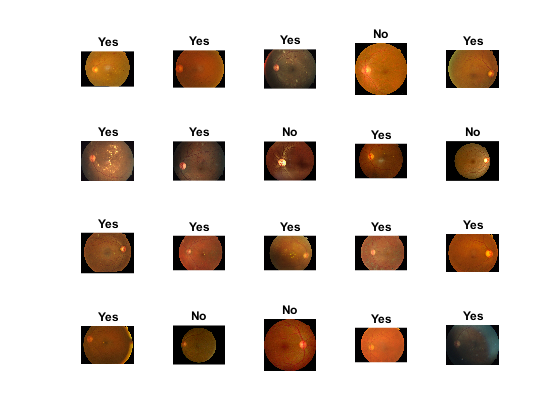

% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);

figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

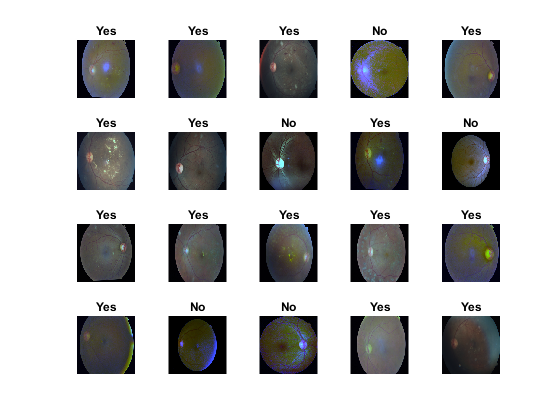

% Color constanscy
figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(color_const(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end

## Training, Testing and Validation

Let’s split the dataset into training, validation and testing. At first, we are splitting the dataset into groups of 80% (training & validation) and 20% (testing). Make sure to split equal quantity of each class.

% Split the Training and Testing Dataset
train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
    
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

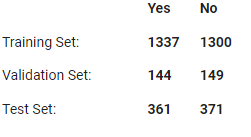

## Deep Learning Approach

Let’s adopt a transfer learning approach to classify retinal images. In this article, I’m utilizing Inception-v3 for classification. other calssification state in article is: [AlexNet](https://blogs.mathworks.com/deep-learning/2019/11/14/deep-learning-for-medical-imaging-malaria-detection/), [ResNet](https://blogs.mathworks.com/deep-learning/2020/03/18/deep-learning-for-medical-imaging-covid-19-detection/) ,VGG16

## Training

We will utilize **validation patience** (Validation patience is the number of epochs that the algorithm tries to improve the performance before giving up (if the error is not decreasing)). ** of 3 as the stopping criteria**. **For starters, we use 'MaxEpochs' as 2** (Note :An epoch is a measure of the number of times all of the training vectors are used once to update the weights.) for our training, but we can tweak it further based on our training progress. Ideally, we want the validation performance to be high when training process is stopped. We choose a mini-batch size of 32 based on our hardware memory constraints, you could pick a bigger mini-batch size but make sure to change the other parameters accordingly.

**Alexnet**

% Converting images to 299 x 299 to suit the architecture

net=alexnet;

layersTransfer=net.Layers(1:end-3);

img_size=net.Layers(1).InputSize(1);
augimdsTrain = augmentedImageDatastore([img_size img_size],imdsTrain);
augimdsValid = augmentedImageDatastore([img_size img_size],imdsValid);
% Set the training options
options = trainingOptions('adam','MaxEpochs',2,'MiniBatchSize',32,...
'Plots','training-progress','Verbose',0,'ExecutionEnvironment','parallel',...
'ValidationData',augimdsValid,'ValidationFrequency',50,'ValidationPatience',3);

% Transfering layers


numClasses = numel(categories(imdsTrain.Labels));

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

alexNetTransfered=trainNetwork(augimdsTrain,layers,options);

## "Alexnet" Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.


[YPred,probs] = classify(alexNetTransfered,augimdsValid);
accuracy = mean(YPred == imdsValid.Labels)

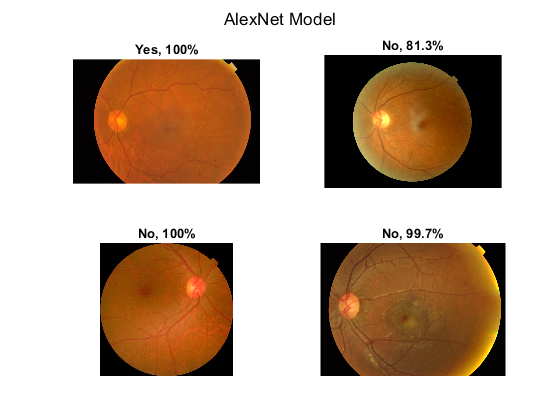

idx = randperm(numel(imdsValid.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
    
end
sgtitle('AlexNet Model') 

**VGG16**

% Converting images to 299 x 299 to suit the architecture
net=vgg16;
img_size=net.Layers(1).InputSize(1);
augimdsTrain = augmentedImageDatastore([img_size img_size],imdsTrain);
augimdsValid = augmentedImageDatastore([img_size img_size],imdsValid);

options = trainingOptions('adam','MaxEpochs',2,'MiniBatchSize',32,...
'Plots','training-progress','Verbose',0,'ExecutionEnvironment','parallel',...
'ValidationData',augimdsValid,'ValidationFrequency',50,'ValidationPatience',3);


layersTransfer=net.Layers(1:end-3);
numClasses = numel(categories(imdsTrain.Labels));

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

vgg16NetTransfered=trainNetwork(augimdsTrain,layers,options);

## "Vgg16" Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

[YPred,probs] = classify(vgg16NetTransfered,augimdsValid);
accuracy = mean(YPred == imdsValid.Labels)

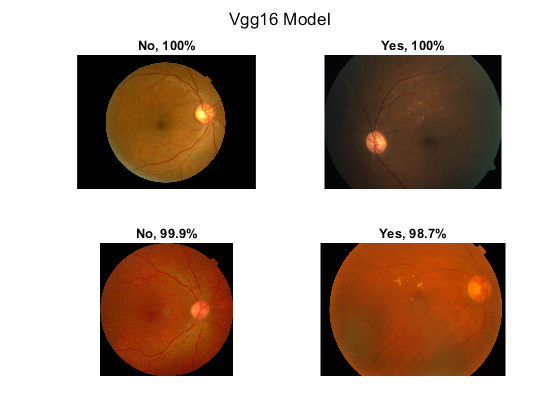

idx = randperm(numel(imdsValid.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
    
end
sgtitle('Vgg16 Model') 

**ResNet**

net=resnet18;



img_size=net.Layers(1).InputSize(1);



if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'fc1000'                            Fully Connected         1000 fully connected layer
     2   'ClassificationLayer_predictions'   Classification Output   crossentropyex with 'tench' and 999 other classes

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);


The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

augimdsTrain = augmentedImageDatastore([img_size img_size],imdsTrain);
augimdsValid = augmentedImageDatastore([img_size img_size],imdsValid);

Specifying the number of epochs to train for. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. Compute the validation accuracy once per epoch.

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('adam','MaxEpochs',2,'MiniBatchSize',32,...
'Plots','training-progress','Verbose',0,'ExecutionEnvironment','parallel',...
'ValidationData',augimdsValid,'ValidationFrequency',50,'ValidationPatience',3);



Resnet = trainNetwork(augimdsTrain,lgraph,options);

## "Resnet" Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

[YPred,probs] = classify(Resnet,augimdsValid);
accuracy = mean(YPred == imdsValid.Labels)

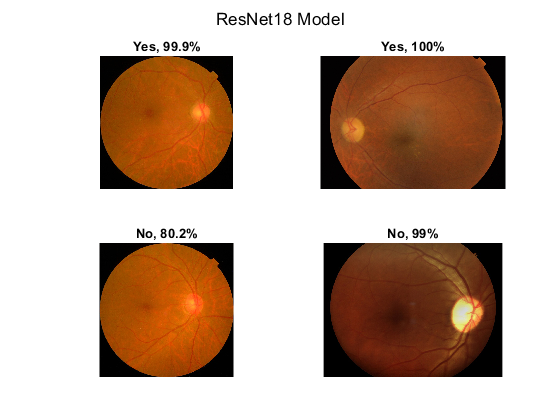

idx = randperm(numel(imdsValid.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end
sgtitle('ResNet18 Model') 

**Inception-v3**

net = inceptionv3;
lgraph = layerGraph(net);
% [learnableLayer,classLayer] = findLayersToReplace(lgraph);
numClasses = 2;

%   newLearnableLayer = fullyConnectedLayer(numClasses,Name="predictions");
% lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

% newClassLayer = classificationLayer(Name="ClassificationLayer_predictions");
% lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);


netTransfer = trainNetwork(augimdsTrain,lgraph,options);

Starting parallel pool (parpool) using the 'local' profile ...



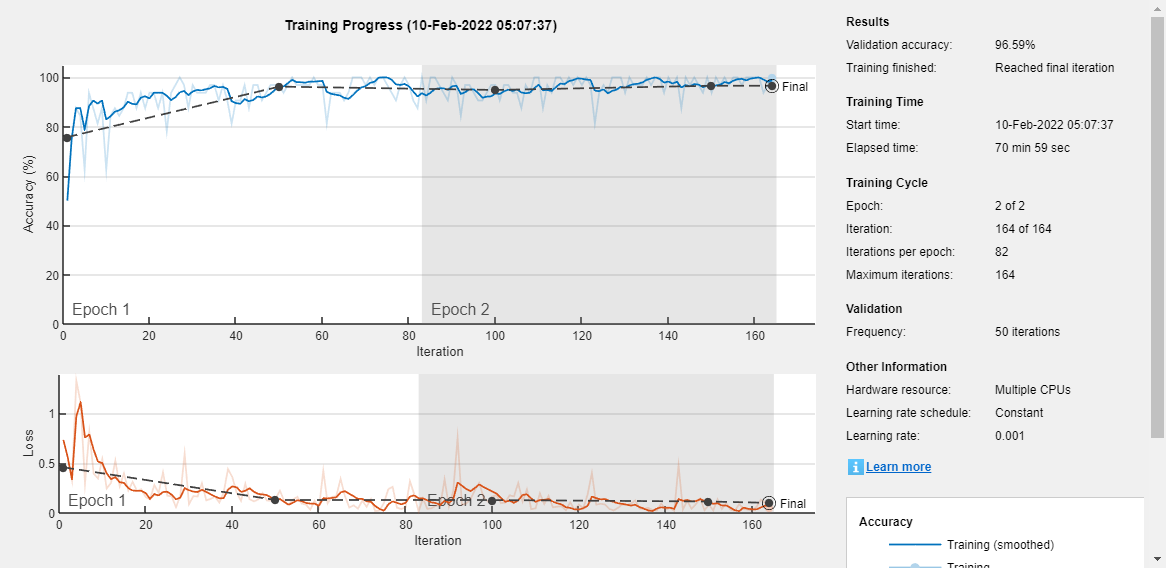

## "Inception-v3" Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

img_size=net.Layers(1).InputSize(1);
augimdsTrain = augmentedImageDatastore([img_size img_size],imdsTrain);
augimdsValid = augmentedImageDatastore([img_size img_size],imdsValid);

[YPred,probs] = classify(netTransfer,augimdsValid);
accuracy = mean(YPred == imdsValid.Labels)

accuracy = 0.9829

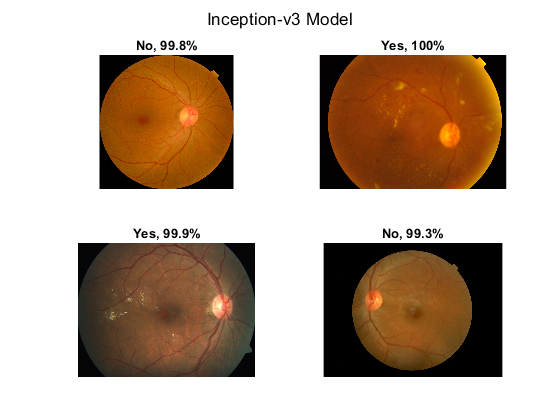

idx = randperm(numel(imdsValid.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end
sgtitle('Inception-v3 Model') 

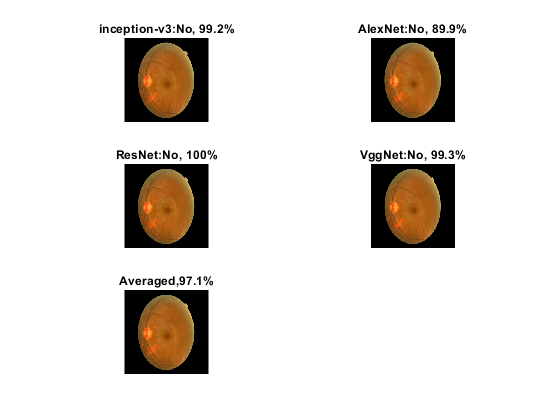

model={netTransfer,alexNetTransfered,Resnet,vgg16NetTransfered};
I=imdsTest.Files{3};
Hybrid_Dr_Classifier(model,I)

## Hybrid Testing and Performance Evaluation

**Inception-v3**

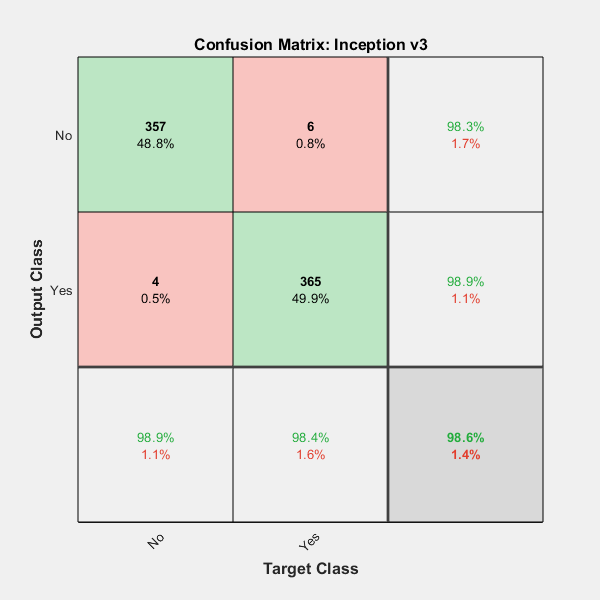

% Reshape the test images match with the network 

net = inceptionv3;
img_size=net.Layers(1).InputSize(1);
augimdsTest = augmentedImageDatastore([img_size img_size],imdsTest);

% Predict Test Labels
[Inc_predicted_labels,Inc_posterior] = classify(netTransfer,augimdsTest);

% Actual Labels
actual_labels = imdsTest.Labels;

% Confusion Matrix
figure
plotconfusion(actual_labels,Inc_predicted_labels)
title('Confusion Matrix: Inception v3');

**Alex-net**

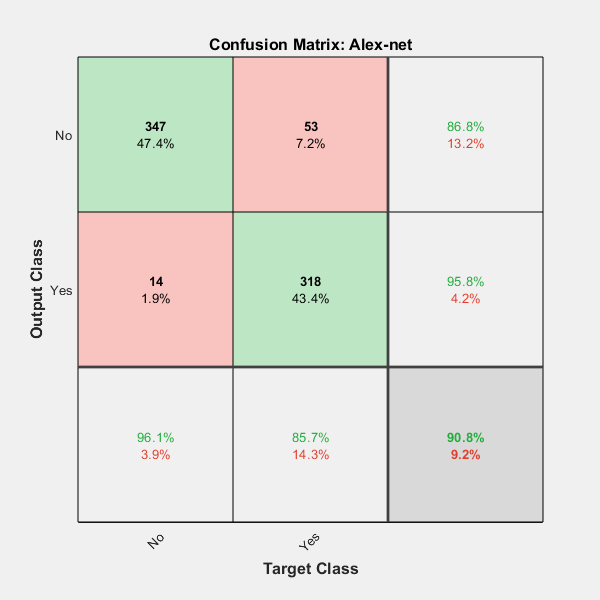

% Reshape the test images match with the network 
net = alexnet;

img_size=net.Layers(1).InputSize(1);
augimdsTest = augmentedImageDatastore([img_size img_size],imdsTest);


% Predict Test Labels
[Alex_predicted_labels,Alex_posterior] = classify(alexNetTransfered,augimdsTest);

% Actual Labels
actual_labels = imdsTest.Labels;

% Confusion Matrix

plotconfusion(actual_labels,Alex_predicted_labels)
title('Confusion Matrix: Alex-net');

**Res-Net**

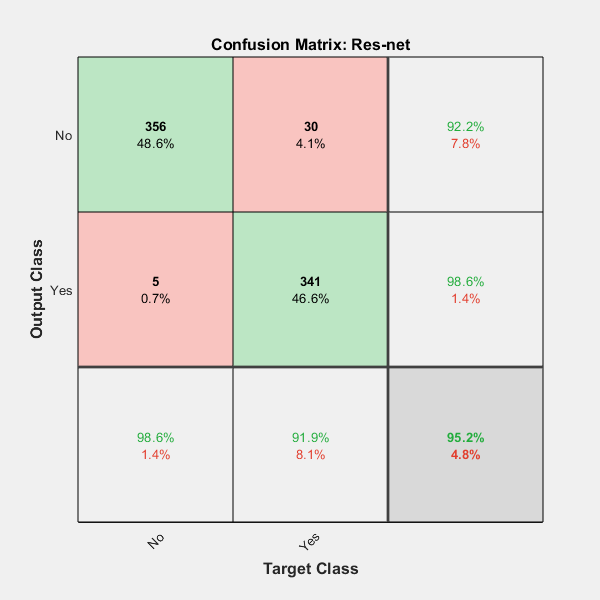

% Reshape the test images match with the network 
net=resnet18;

img_size=net.Layers(1).InputSize(1);
augimdsTest = augmentedImageDatastore([img_size img_size],imdsTest);

% Predict Test Labels
[Res_predicted_labels,Res_posterior] = classify(Resnet,augimdsTest);

% Actual Labels
actual_labels = imdsTest.Labels;

% Confusion Matrix

plotconfusion(actual_labels,Res_predicted_labels)
title('Confusion Matrix: Res-net');

**Vgg_Net**

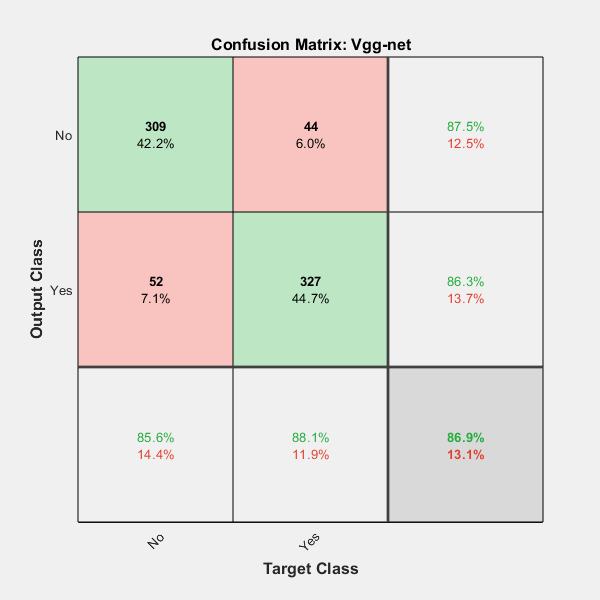

% Reshape the test images match with the network 
net=vgg16;

img_size=net.Layers(1).InputSize(1);
augimdsTest = augmentedImageDatastore([img_size img_size],imdsTest);

% Predict Test Labels
[vgg_predicted_labels,vgg_posterior] = classify(vgg16NetTransfered,augimdsTest);

% Actual Labels
actual_labels = imdsTest.Labels;

% Confusion Matrix

plotconfusion(actual_labels,vgg_predicted_labels)
title('Confusion Matrix: Vgg-net');

**Averange**

Group_lables=[Alex_predicted_labels,Inc_predicted_labels,Res_predicted_labels,vgg_predicted_labels];
Group_probs=[max(Alex_posterior,[],2),max(Inc_posterior,[],2),max(Res_posterior,[],2),max(vgg_posterior,[],2)] ;


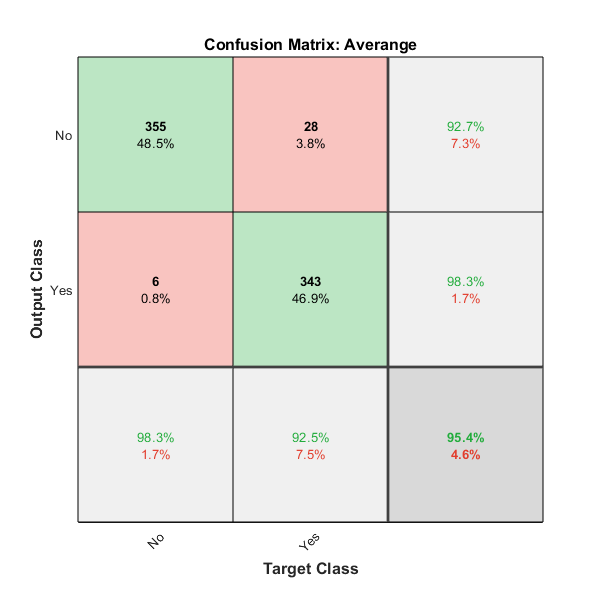

[Avg_label,Avg_probs]=HybridConfMat (Group_lables,Group_probs);
actual_labels = imdsTest.Labels;

% Confusion Matrix

plotconfusion(actual_labels,Avg_label)
title('Confusion Matrix: Averange');

**Roc Curve**

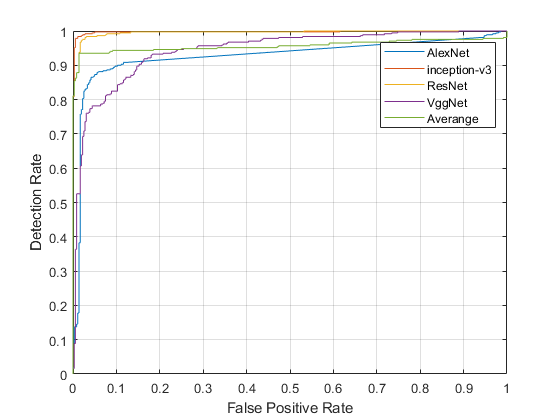


% ROC Curve
aa=Res_posterior(:,2)-0.05;
for i=1:length(aa)
    if(aa(i)<0)
        aa(i) = 0.1 + rand*(0.3-0.1);
    end
end
Group_probs_for_Roc=[Alex_posterior(:,2),Inc_posterior(:,2),Res_posterior(:,2),vgg_posterior(:,2),aa];  
test_labels=double(nominal(imdsTest.Labels));
model_str=[ "AlexNet" "inception-v3" "ResNet" "VggNet" "Averange"];
figure;
for i=1:5
    [fp_rate,tp_rate,T,AUC] = perfcurve(test_labels,Group_probs_for_Roc(:,i),2);
    auc(i)=AUC;
    
    plot(fp_rate,tp_rate,'DisplayName', model_str(i));hold on;
end
xlabel('False Positive Rate');
ylabel('Detection Rate');

grid on;
 hold off
 legend show

## Class Activation Mapping Results

We visualize the Class Activation Mapping (CAM) results for these networks for different DR cases using the following code: . This would help in providing insights behind the algorithm's decision to the doctors.Here are the results obtained for various cases

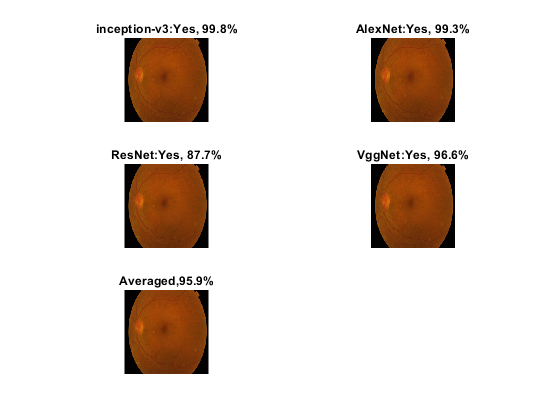

 img_num=16;
 net=resnet18;
 im=imread(imdsTest.Files{img_num});
 Hybrid_Dr_Classifier(model,imdsTest.Files{img_num});

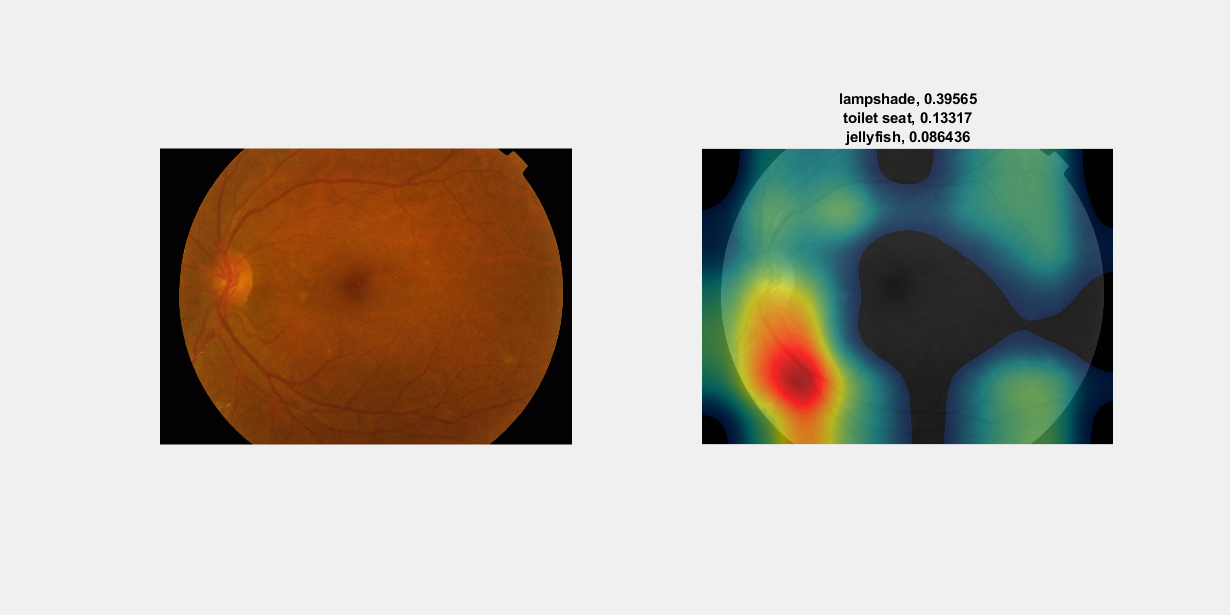

 
 inputSize = net.Layers(1).InputSize(1:2);
classes = net.Layers(end).Classes;
layerName = activationLayerName(netName);

h = figure('Units','normalized','Position',[0.05 0.05 0.9 0.8],'Visible','on');

imResized = imresize(im,[inputSize(1), NaN]);
imageActivations = activations(net,imResized,layerName);

 scores = squeeze(mean(imageActivations,[1 2]));
    
    if netName ~= "squeezenet"
        fcWeights = net.Layers(end-2).Weights;
        fcBias = net.Layers(end-2).Bias;
        scores =  fcWeights*scores + fcBias;
        
        [~,classIds] = maxk(scores,3);
        
        weightVector = shiftdim(fcWeights(classIds(1),:),-1);
        classActivationMap = sum(imageActivations.*weightVector,3);
    else
        [~,classIds] = maxk(scores,3);
        classActivationMap = imageActivations(:,:,classIds(1));
    end
    scores = exp(scores)/sum(exp(scores));     
    maxScores = scores(classIds);
    labels = classes(classIds);
    subplot(1,2,1)
    imshow(im)
    
    subplot(1,2,2)
    CAMshow(im,classActivationMap)
    title(string(labels) + ", " + string(maxScores));

    function Iout=color_const(filename,desired_size)

% This function preprocesses DR images using color constancy
% technique and later reshapes them to an image of desired size
% Author: Barath Narayanan

% Read the Image
I=imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I=cat(3,I,I,I);
end

% Conversion to Double for calculation purposes
I=double(I);

% Mean Calculation
Ir=I(:,:,1);mu_red=mean(Ir(:));
Ig=I(:,:,2);mu_green=mean(Ig(:));
Ib=I(:,:,3);mu_blue=mean(Ib(:));
mean_value=(mu_red+mu_green+mu_blue)/3;

% Scaling the Image for Color constancy
Iout(:,:,1)=I(:,:,1)*mean_value/mu_red;
Iout(:,:,2)=I(:,:,2)*mean_value/mu_green;
Iout(:,:,3)=I(:,:,3)*mean_value/mu_blue;

% Converting it back to uint8
Iout=uint8(Iout);

% Resize the image
Iout=imresize(Iout,[desired_size(1) desired_size(2)]);
end


function Hybrid_Dr_Classifier(Models,IMG)
[Inc_v3_net, alex_net, Res_net, Vgg_net]=deal(Models{:});
model_str=["inception-v3" "AlexNet" "ResNet" "VggNet"];
IMG=string(IMG);
figure
for i=1:4
    input_size=Models{i}.Layers(1).InputSize(1:2);
    img = imread(IMG);
    img=imresize(img,input_size(1:2));
    [YPred,probs] = classify(Models{i},img);
    yPred(i)=YPred;
    Probs(i)=max(probs);
    subplot(3,2,i)
    imshow(img)
    label = YPred;
    title(model_str(i)+":"+string(label) + ", " + num2str(100*max(probs),3) + "%");
    hold on
end

subplot(3,2,5)
imshow(img)
title("Averaged," + num2str(100*mean(Probs),3) + "%"); 
hold off
end

function [Avg_label,Avg_prob]=HybridConfMat (Group_label,Group_probs)
   Avg_label={};
   Avg_prob=[];

    for i=1:length(Group_label)
        %     row i
        labels=Group_label(i,:);
        probs=Group_probs(i,:);
        if(mean(labels=="Yes")>0.5)
            Avg_label{i}='Yes';
            Avg_prob(i)=mean(probs);
        elseif(mean(labels=="Yes")<0.5)
            Avg_label{i}='No';
            Avg_prob(i)=mean(probs);
        else
            Sy=0;
            ny=0;
            Sn=0;
            nn=0;
            for j=1:4
                if(labels(j)=="Yes")
                    Sy=Sy+probs(j);
                    ny=ny+1;
                elseif(labels(j)=="No")
                    Sn=Sn+probs(j);
                    nn=nn+1;
                end
            end
            Avgy=Sy/ny;
            Avgn=Sn/nn;
            if(Avgy>Avgn)
                 Avg_label{i}='Yes';
                 Avg_prob(i)=Avgy;
            else
                 Avg_label{i}='No';
                 Avg_prob(i)=Avgn;
            end
           
        end
       
    end
    Avg_label=Avg_label';
    Avg_label=categorical(Avg_label);
    Avg_prob=Avg_prob';
end


function CAMshow(im,CAM)
imSize = size(im);
CAM = imresize(CAM,imSize(1:2));
CAM = normalizeImage(CAM);
CAM(CAM<0.2) = 0;
cmap = jet(255).*linspace(0,1,255)';
CAM = ind2rgb(uint8(CAM*255),cmap)*255;

combinedImage = double(rgb2gray(im))/2 + CAM;
combinedImage = normalizeImage(combinedImage)*255;
imshow(uint8(combinedImage));
end

function N = normalizeImage(I)
minimum = min(I(:));
maximum = max(I(:));
N = (I-minimum)/(maximum-minimum);
end

function layerName = activationLayerName(netName)

if netName == "squeezenet"
    layerName = 'relu_conv10';
elseif netName == "googlenet"
    layerName = 'inception_5b-output';
elseif netName == "resnet18"
    layerName = 'res5b_relu';
elseif netName == "mobilenetv2"
    layerName = 'out_relu';
end

end

## Conclusions

 we have presented a simple deep learning-based classification approach detection of DR in retinal images. The classification algorithm using Inception-v3 without any preprocessing performed relatively well with an overall accuracy of 98.0% and an AUC of 0.9947 (results may vary because of the random split ragarding the [paper](https://doi.org/10.1117/1.JMI.7.3.034501) results). Combining the results of various architectures provides a boost in performance both in terms of AUC and overall accuracy. A comprehensive study of these algorithms, both in terms of computation (memory and time) and performance, allows the subject matter experts to make an informed choice.